alpha = 1 + mod(282,3)

alpha = 1

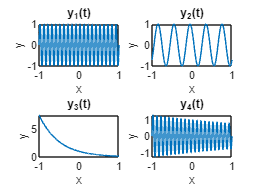

%question 1
t = linspace(-1,1,1000);
y1 = sin(20*pi*alpha*t);
subplot(2,2,1);
plot(t,y1)
xlabel('x'); 
ylabel ('y');
title('y_1(t)');

y2= cos(5*pi*alpha*t + (pi/4));
subplot(2,2,2);
plot(t,y2);
xlabel('x'); 
ylabel ('y');
title('y_2(t)');

y3 = exp(-2*alpha*t);
subplot(2,2,3);
plot(t,y3);
xlabel('x'); 
ylabel ('y');
title('y_3(t)');

y4 = (exp(-0.25*alpha*t)).*(sin(20*pi*t));
subplot(2,2,4);
plot(t,y4);
xlabel('x'); 
ylabel ('y');
title('y_4(t)');

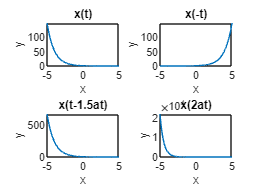

%question 2

t = linspace(-5,5,1000);
subplot(2,2,1);
x= @(t) exp(-alpha*t);
plot(t,x(t));
xlabel('x'); 
ylabel ('y');
title('x(t)')

subplot(2,2,2);
plot(t,x(-t));
xlabel('x'); 
ylabel ('y');
title('x(-t)')

subplot(2,2,3);
plot(t,x(t-(1.5*alpha)))
xlabel('x'); 
ylabel ('y');
title('x(t-1.5at)')

subplot(2,2,4);
plot(t,x(2*alpha*t))
xlabel('x'); 
ylabel ('y');
title('x(2at)')

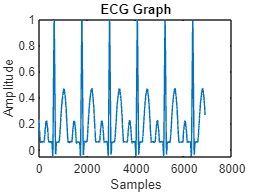

% question 3-1
ECG_Data = importdata('ECG_Data.txt');
subplot(1,1,1);
plot(ECG_Data);
xlabel('Samples')
ylabel('Amplitude')
title('ECG Graph')

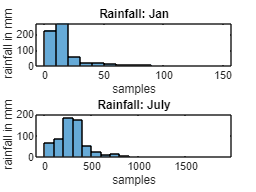

% question 3-2
RainFall_Jan = importdata('RainFallIndia_Jan.txt');
RainFall_July = importdata('RainFallIndia_July.txt');

subplot(2,1,1);
histogram(RainFall_Jan);
xlabel('samples')
ylabel('rainfall in mm')
title('Rainfall: Jan')

subplot(2,1,2);
histogram(RainFall_July);
xlabel('samples')
ylabel('rainfall in mm')
title('Rainfall: July')


disp('Mean rainfall - Jan');

Mean rainfall - Jan


mean(RainFall_Jan)

ans = 18.3513

disp('Mean rainfall - July');

Mean rainfall - July


mean(RainFall_July)

ans = 326.0936


disp('standard deviation - Jan');

standard deviation - Jan


std(RainFall_Jan)

ans = 21.0991

disp('standard deviation - July');

standard deviation - July


std(RainFall_July)

ans = 221.5326

% question 3-3
audio_data= importdata('track002.wav');
[y,Fs] = audioread('track002.wav'); 
%reads data from the file named filename, and returns sampled data, y, and a sample rate for that data, Fs.
sound(y,Fs);

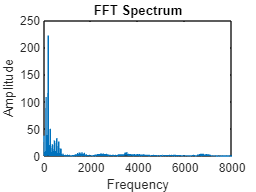

%question 4
[y,Fs] = audioread('speech.wav');

t=linspace(0,length(y)/Fs,length(y));
Nfft=16777216; %power of 2 and I put a huge number so there are many data point
f=linspace(0,Fs,Nfft);
X1=abs(fft(y,Nfft));
figure(2);
plot(f(1:Nfft/2),X1(1:Nfft/2))
xlabel('Frequency'); 
ylabel ('Amplitude');
title ('FFT Spectrum');

%5
% Parameters
num_samples = 5000;
alpha = 1; % You can adjust this value to change the frequency scaling
freq_1 = 200 * alpha;
freq_2 = 220 * alpha;
duration = 1.0; % 1 second
sampling_rate = 44100; % CD quality sampling rate

% Time vector
time = (0:num_samples-1) / sampling_rate;

% Generate sinusoids
sinusoid_1 = 0.5 * sin(2 * pi * freq_1 * time);
sinusoid_2 = 0.5 * sin(2 * pi * freq_2 * time);

% Concatenate them
combined_signal = [sinusoid_1, sinusoid_2];

% Write to .wav file
output_file = 'output.wav';
audiowrite(output_file, combined_signal, sampling_rate);

disp(['File saved to' output_file]);

File saved tooutput.wav


[s, fs] = audioread('output.wav');
sound(s,fs)

%6
% Define frequencies for each note
freqs = [261.63, 293.66, 329.63, 349.23, 392.00, 440.00, 493.88, 523.25]; % Frequencies in Hz

% Define the duration of each note (in seconds)
note_duration = 0.5; % Duration of each note

% Create the time vector
fs = 44100; % Sampling frequency in Hz
t = 0:1/fs:note_duration-1/fs; % Time vector for one note

% Initialize the signal
signal = [];

% Generate the tones and append them to the signal
for i = 1:length(freqs)
    tone = sin(2 * pi * freqs(i) * t);
    signal = [signal, tone];
end

% Save the signal as a .wav file
filename = 'music.wav';
audiowrite(filename, signal, fs);

disp('File saved successfully.');

File saved successfully.


[s, fs] = audioread('music.wav');
sound(s,fs)

%7
% Load the audio data
audio_filename = 'Track002.wav';
[audio_data, fs] = audioread(audio_filename);

% Load the filter coefficients
filter_filename = 'ConvFile2.txt';
filter_coeffs = load(filter_filename);

% Perform convolution
conv_result = conv(audio_data, filter_coeffs);

% Save the result as a .wav file
output_filename = 'convolved_output.wav';
audiowrite(output_filename, conv_result, fs);

disp('Convolution and file saving completed.');

Convolution and file saving completed.


[s, fs] = audioread('convolved_output.wav');
sound(s,fs)

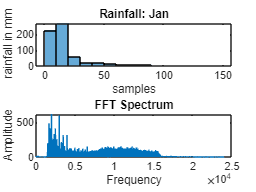

%7
load("ConvFile2.txt");
[y,Fs] = audioread('track002.wav');
C = conv2(ConvFile2,y);
filename = 'exp1_4.wav';
audiowrite(filename,C,Fs);
[C,Fs] = audioread('exp1_4.wav');

[y4,Fs]=audioread('exp1_4.wav');
t=linspace(0,length(y4)/Fs,length(y4));
Nfft=16777216; %power of 2 and I put a huge number so there are many data point
f=linspace(0,Fs,Nfft);
X1=abs(fft(y4,Nfft));
figure(1);
plot(f(1:Nfft/2),X1(1:Nfft/2))
xlabel('Frequency'); 
ylabel ('Amplitude');
title ('FFT Spectrum');

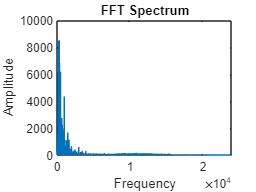


[y,Fs]=audioread('Track002.wav');
t=linspace(0,length(y)/Fs,length(y));
Nfft=16777216; %power of 2 and I put a huge number so there are many data point
f=linspace(0,Fs,Nfft);
X1=abs(fft(y,Nfft));
figure(2);
plot(f(1:Nfft/2),X1(1:Nfft/2))
xlabel('Frequency'); 
ylabel ('Amplitude');
title ('FFT Spectrum');